% Based on the example:
% Simulations In Three Dimensions Example
% Trying to implement ObjectBackscatter.mlx in 3D
% COULD USE KWAVETRANSDUCER() CLASS WITH 3D - although attempting without
% first
% ULTRASOUND TRANSDUCER EXAMPLE SHOWS TURNING A TONE BURST INTO ONE PULSE,
% COULD IMPLEMENT THIS
clearvars;
% create the computational grid
xSize = 0.7;        % height of grid in meters
ySize = 0.3;        % length of grid in meters
zSize = 0.1;        % width of grid in meters
Nx = 128;           % number of grid points in the x (row) direction
Ny = 64;            % number of grid points in the y (column) direction
Nz = 64;            % number of grid points in the z (slice) direction
dx = xSize/Nx;    	% grid point spacing in the x direction [m]
dy = ySize/Ny;      % grid point spacing in the y direction [m]
dz = zSize/Nz;      % grid point spacing in the z direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);

% define sound speed in the two layers
c1 = 1500;          % water
c2 = 5100;          % aluminium
% define the properties of the propagation medium
medium.sound_speed = c1 * ones(Nx, Ny,Nz);     % [m/s]
medium.sound_speed(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3, Nz/2-3:Nz/2+3) = c2;
medium.density = 1000 * ones(Nx, Ny,Nz);       % [kg/m^3]
medium.density(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3, Nz/2-3:Nz/2+3) = 2700;

% create the time array
kgrid.makeTime(medium.sound_speed);
kgrid.Nt

ans = 5572

kgrid.Nt = 1000

kgrid =   kWaveGrid with properties:

                   Nx: 128
                   Ny: 64
                   Nz: 64
                   dx: 0.0055
                   dy: 0.0047
                   dz: 0.0016
               kx_vec: [128×1 double]
               ky_vec: [64×1 double]
               kz_vec: [64×1 double]
                    k: [128×64×64 double]
               kx_max: 574.4627
               ky_max: 670.2064
               kz_max: 2.0106e+03
                k_max: 574.4627
                  dim: 3
           nonuniform: 0
                   dt: 9.1912e-08
                   Nt: 1000
                x_vec: [128×1 double]
                y_vec: [64×1 double]
                z_vec: [64×1 double]
                    x: [128×64×64 double]
                    y: [128×64×64 double]
                    z: [128×64×64 double]
                   kx: [128×64×64 double]
                   ky: [128×64×64 double]
         

kgrid.dt

ans = 9.1912e-08

Running k-Wave simulation...
  start time: 28-Apr-2023 12:51:33
  reference sound speed: 5100m/s
  dt: 91.9118ns, t_end: 91.8199us, time steps: 1000
  input grid size: 128 by 64 by 64 grid points (700 by 300 by 100mm)
  maximum supported frequency: 137.1429kHz by 160kHz by 480kHz
  expanding computational grid...
  computational grid size: 148 by 84 by 84 grid points
           Use dimension sizes with lower prime factors to improve speed


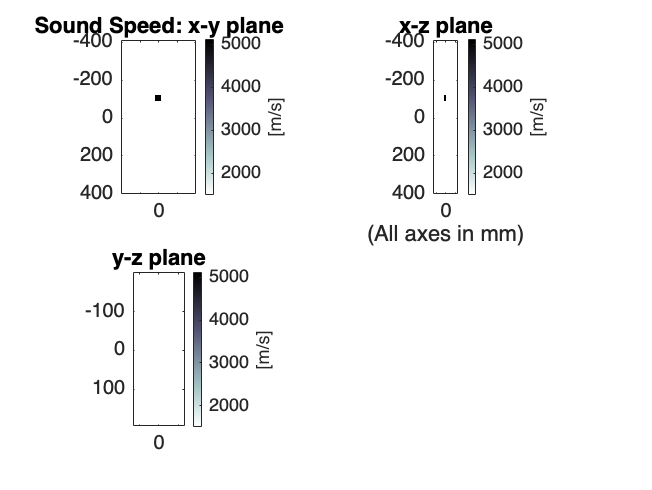

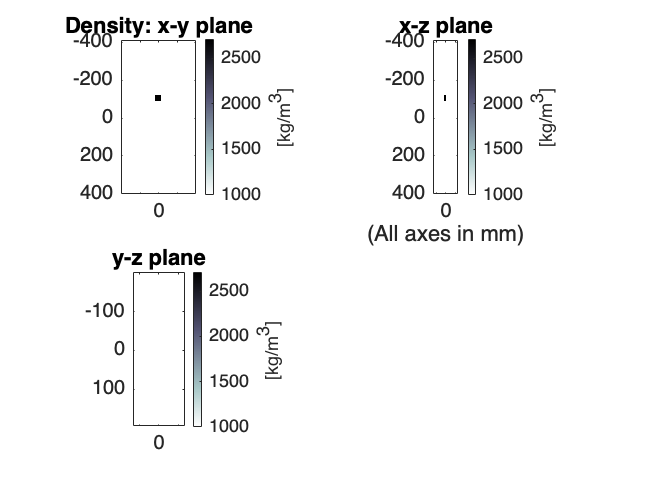

  precomputation completed in 1.2842s
  starting time loop...
  estimated simulation time 2min 16.9131s...


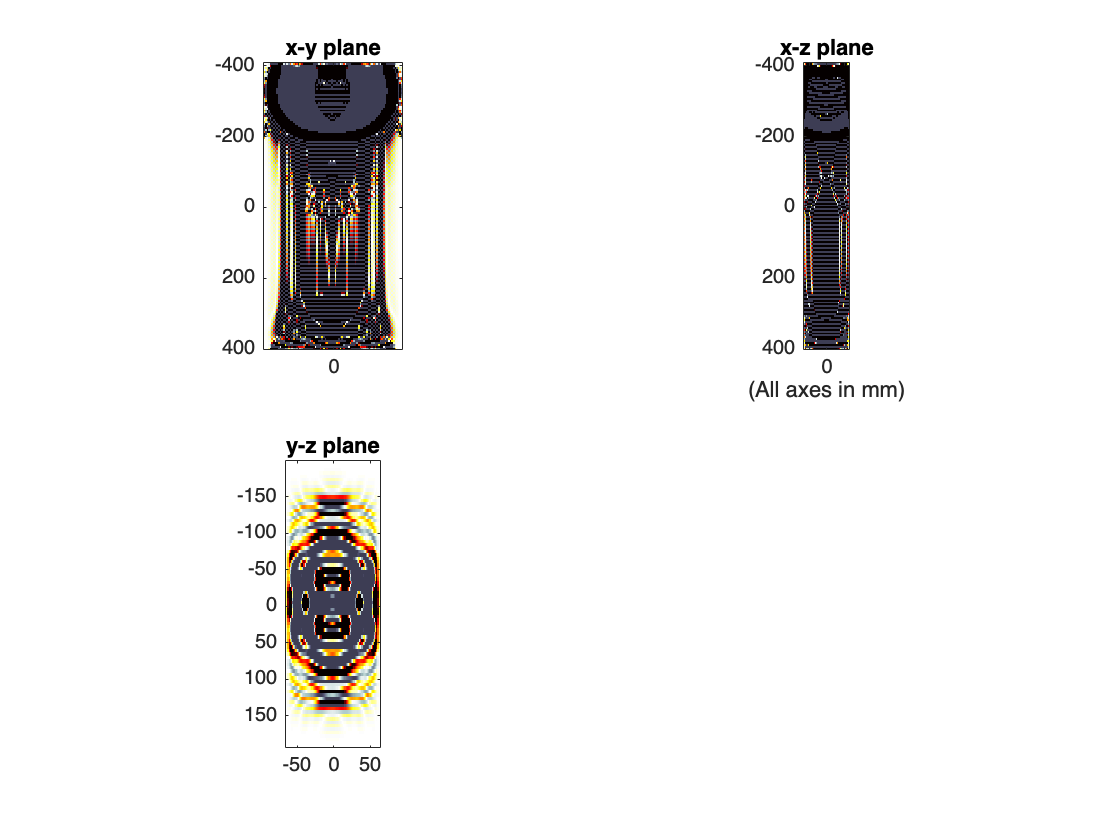

  simulation completed in 2min 4.8509s
  total computation time 2min 6.1771s



% using source from ewp 3D example
num_elements = 21;
x_offset = 5;
y_offset = Ny/2 - round(num_elements/2) + 1;
z_offset = Nz/2 - round(num_elements/2) + 1;
source.p_mask = zeros(Nx, Ny, Nz);
source.p_mask(x_offset, y_offset:y_offset + num_elements - 1, z_offset:z_offset + num_elements - 1) = 1;

source_freq = 200e3;      % [Hz]
source_mag = 1e6;    % [MPa]
source_cycles = 5;
source.p = source_mag * toneBurst(1/kgrid.dt, source_freq, source_cycles);
% use envelope detection
source.p = envelopeDetection(source.p);

% assign the input options
input_args = {'DisplayMask', source.p_mask, 'PMLInside', false, 'PlotLayout', true};

%define sensor mask
sensor.mask = zeros(Nx, Ny, Nz);
sensor.mask(x_offset, y_offset:y_offset + num_elements - 1, z_offset:z_offset + num_elements - 1) = 1;

% run the simulation
sensor_data = kspaceFirstOrder3D(kgrid, medium, source, sensor, input_args{:});

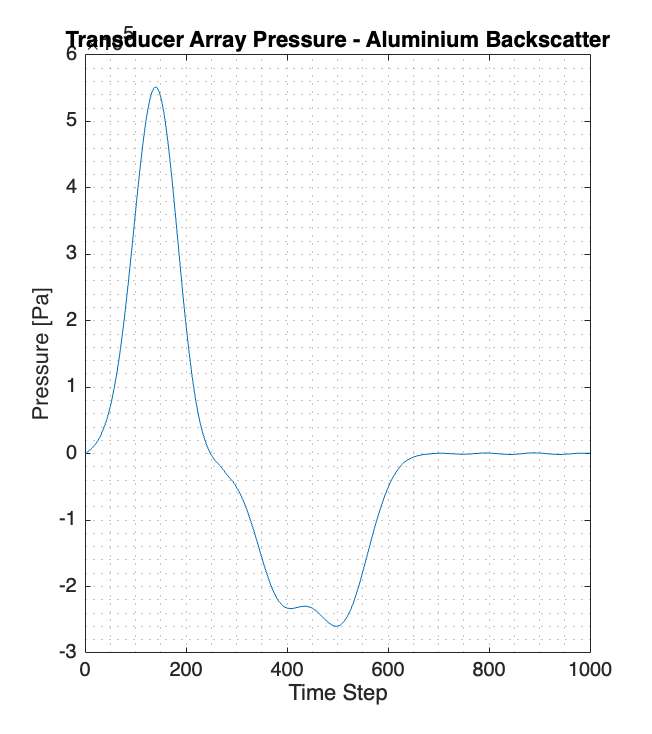


%plot pressure data at middle element
mid_element = round(num_elements/2);
figure;
plot(sensor_data(mid_element, :));
xlabel('Time Step');
ylabel('Pressure [Pa]');
title("Transducer Array Pressure - Aluminium Backscatter")
scaleFig(1, 1.5);
grid minor;